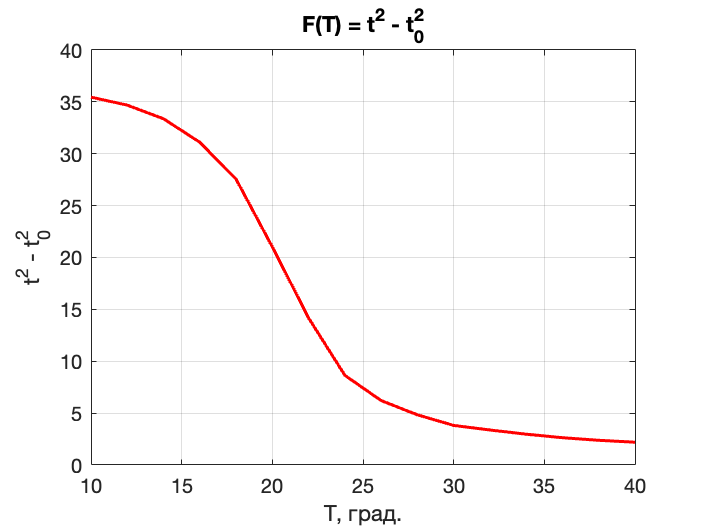

data = importdata('lab342.xlsx');

tau_0 = 8.252;

squares = power(data(:, 2), 2);

tau_square = tau_0.^2;

y1 = squares - tau_square;
y2 = y1.^-1;

fig1 = figure;
plot(data(:, 1), y1, LineWidth=1.5, color='red');
grid on
xlabel('T, град.');
ylabel('t^2 - t_0^2');
title('F(T) = t^2 - t_0^2');
saveas(fig1, 'first.png')


to_fit_y = y2(7:end, :);
to_fit_x = data(7:end, 1);
plf = polyfit(to_fit_x, to_fit_y, 1)

plf =     0.0216   -0.3976


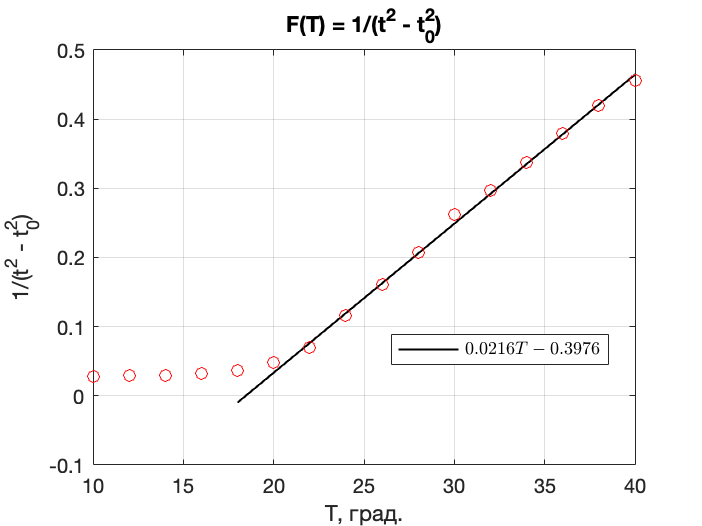

y_fitted = polyval(plf, data(5:end, 1));

fig2 = figure;
plot(data(5:end, 1), y_fitted, Color='black', LineWidth=1)
hold on
scatter(data(:, 1), y2, MarkerEdgeColor='red');
hold off
grid on
legend('$0.0216 T - 0.3976$', 'Interpreter', 'latex', Location='best')
xlabel('T, град.');
ylabel('1/(t^2 - t_0^2)');
title('F(T) = 1/(t^2 - t_0^2)');
saveas(fig2, 'second.png')


T_0 = 0.3976/0.0216

T_0 = 18.4074